# Analisi delle singolarità per il robot RRR planare

Lo jacobiano analitico del robot planare RRR è

syms q1 q2 q3
J = [-sin(q1)-sin(q1+q2)-sin(q1+q2+q3), -sin(q1+q2)-sin(q1+q2+q3), -sin(q1+q2+q3); 
     cos(q1)+cos(q1+q2)+cos(q1+q2+q3), cos(q1+q2)+cos(q1+q2+q3), cos(q1+q2+q3)]

$$J = \left(\begin{array}{ccc} -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

Al fine di individuare le singolarità si analizzano le soluzioni dell'equazione $\det(\mathbf J\mathbf J^T)=0$.

JJT = J*(J.')

$$JJT = \begin{array}{l} \left(\begin{array}{cc} {\sigma_{2}}^{2}+{\sigma_{4}}^{2}+{\left(\sigma_{4}+\sin\left(q_{1}+q_{2}\right)\right)}^{2} & \sigma_{1}\\ \sigma_{1} & {\sigma_{3}}^{2}+{\sigma_{5}}^{2}+{\left(\sigma_{5}+\cos\left(q_{1}+q_{2}\right)\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\sigma_{2}\,\sigma_{3}-\sigma_{5}\,\sigma_{4}-\left(\sigma_{5}+\cos\left(q_{1}+q_{2}\right)\right)\,\left(\sigma_{4}+\sin\left(q_{1}+q_{2}\right)\right)\\ \sigma_{2}=\sigma_{4}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\\ \sigma_{3}=\sigma_{5}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\\ \sigma_{4}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{5}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

simplify(det(JJT))

$$ans = \cos\left(q_{2}\right)-\cos\left(2\,q_{2}+q_{3}\right)-\frac{\cos\left(2\,q_{2}\right)}{2}-\cos\left(2\,q_{3}\right)-\cos\left(2\,q_{2}+2\,q_{3}\right)-\cos\left(q_{2}+2\,q_{3}\right)+\cos\left(q_{3}\right)+\frac{5}{2}$$

Secondo WolframAlpha tale equazione si annulla in:


$$q_2 = \pi n_1\quad\quad q_3=2\pi n_2\quad\quad n_1\in\mathbb{Z}\quad\quad n_2\in\mathbb{Z}$$



$$q_2 = 2\pi n_1+\pi\quad\quad q_3=2\pi n_2+\pi\quad\quad n_1\in\mathbb{Z}\quad\quad n_2\in\mathbb{Z}$$



$$q_2 = 2\pi n_2\quad\quad q_3=2\pi n_1+\pi\quad\quad n_1\in\mathbb{Z}\quad\quad n_2\in\mathbb{Z}$$


Vedi: [https://www.wolframalpha.com/input?i2d=true&i=det%5C%2840%29%7B%7B-sin%5C%2840%29q1%5C%2841%29-sin%5C%2840%29q1%2Bq2%5C%2841%29-sin%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2C-sin%5C%2840%29q1%2Bq2%5C%2841%29-sin%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2C-sin%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%7D%2C%7Bcos%5C%2840%29q1%5C%2841%29%2Bcos%5C%2840%29q1%2Bq2%5C%2841%29%2Bcos%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2Ccos%5C%2840%29q1%2Bq2%5C%2841%29%2Bcos%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2Ccos%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%7D%7D*%7B%7B-sin%5C%2840%29q1%5C%2841%29-sin%5C%2840%29q1%2Bq2%5C%2841%29-sin%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2Ccos%5C%2840%29q1%5C%2841%29%2Bcos%5C%2840%29q1%2Bq2%5C%2841%29%2Bcos%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%7D%2C%7B-sin%5C%2840%29q1%2Bq2%5C%2841%29-sin%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2Ccos%5C%2840%29q1%2Bq2%5C%2841%29%2Bcos%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%7D%2C%7B-sin%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2Ccos%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%7D%7D%5C%2841%29%3D0](https://www.wolframalpha.com/input?i2d=true&i=det%5C%2840%29%7B%7B-sin%5C%2840%29q1%5C%2841%29-sin%5C%2840%29q1%2Bq2%5C%2841%29-sin%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2C-sin%5C%2840%29q1%2Bq2%5C%2841%29-sin%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2C-sin%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%7D%2C%7Bcos%5C%2840%29q1%5C%2841%29%2Bcos%5C%2840%29q1%2Bq2%5C%2841%29%2Bcos%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2Ccos%5C%2840%29q1%2Bq2%5C%2841%29%2Bcos%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2Ccos%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%7D%7D*%7B%7B-sin%5C%2840%29q1%5C%2841%29-sin%5C%2840%29q1%2Bq2%5C%2841%29-sin%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2Ccos%5C%2840%29q1%5C%2841%29%2Bcos%5C%2840%29q1%2Bq2%5C%2841%29%2Bcos%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%7D%2C%7B-sin%5C%2840%29q1%2Bq2%5C%2841%29-sin%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2Ccos%5C%2840%29q1%2Bq2%5C%2841%29%2Bcos%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%7D%2C%7B-sin%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%2Ccos%5C%2840%29q1%2Bq2%2Bq3%5C%2841%29%7D%7D%5C%2841%29%3D0)

Si ha quindi singolarità in


$$q_2 = 0 \land q_3=0$$



$$q_2 = \pi \land q_3 = 0$$



$$q_2 = \pi \land q_3 = \pi$$



$$q_2 = 0 \land q_3 = \pi$$


## Rango di J

Al fine di individuare le singolarità è anche possibile determinare le configurazioni per cui la matrice $\mathbf J$ perde di rango. Si considerano quindi le sue sottomatrice 2x2.

### J12

J12 = J(1:2,1:2)

$$J12 = \left(\begin{array}{cc} -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right)\\ \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

detJ12 = simplify(det(J12))

$$detJ12 = \sin\left(q_{2}+q_{3}\right)+\sin\left(q_{2}\right)$$

Quindi il blocco $\mathbf J_{12}$ (prime due colonne di $\mathbf J$) perde di rango nel caso in cui $q_3 = -2q_2$.

J121 = simplify(subs(J,q3,-2*q2))

$$J121 = \left(\begin{array}{ccc} -\sin\left(q_{1}\right)\,\left(2\,\cos\left(q_{2}\right)+1\right) & -2\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{1}-q_{2}\right)\\ \cos\left(q_{1}\right)\,\left(2\,\cos\left(q_{2}\right)+1\right) & 2\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \cos\left(q_{1}-q_{2}\right) \end{array}\right)$$

det(J121(:,[1 2]))

$$ans = 0$$

simplify(det(J121(:,[1 3])))

$$ans = -\sin\left(2\,q_{2}\right)-\sin\left(q_{2}\right)$$

Tale determinante si annulla solo per 


$$q_2 = n\pi\quad\quad n\in\mathbb{Z}$$



$$q_2 = \frac{\pi}{3}+2\pi n \quad\quad n\in\mathbb{Z}$$



$$q_2 = \frac{5\pi}{3}+2\pi n \quad\quad n\in\mathbb{Z}$$


simplify(det(J121(:,[2 3])))

$$ans = -\sin\left(2\,q_{2}\right)$$

Tale determinante si anulla per $q_2 = 0,\pi$.

Quindi la matrice $\mathbf J$ perde di rango per


$$q_2 = 0 \land q_3 = 0$$



$$q_2 = \pi \land q_3 = 0$$


### J23

J23 = J(1:2,2:3)

$$J23 = \left(\begin{array}{cc} -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

detJ23 = simplify(det(J23))

$$detJ23 = \sin\left(q_{3}\right)$$

Il blocco 2x2 $\mathbf J_{23}$ costituito dalle ultime due colonne di $\mathbf J$ perde di rango nel caso in cui $q_3 = 0 \lor q_3 = \pi$.

J231 = subs(J,[q3],[0])

$$J231 = \left(\begin{array}{ccc} -2\,\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -2\,\sin\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right)\\ 2\,\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & 2\,\cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

simplify(det(J231(:,[1 3])))

$$ans = \sin\left(q_{2}\right)$$

Nel caso $q_3 = 0$ la matrice $\mathbf J$ perde di rango se $q_2 = 0 \lor q_2 = \pi$.

J231 = subs(J,[q3],[pi])

$$J231 = \left(\begin{array}{ccc} -\sin\left(q_{1}\right) & 0 & \sin\left(q_{1}+q_{2}\right)\\ \cos\left(q_{1}\right) & 0 & -\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

simplify(det(J231(:,[1 3])))

$$ans = -\sin\left(q_{2}\right)$$

Nel caso $q_3 = \pi$ la matrice $\mathbf J$ perde di rango se $q_2 = 0 \lor q_2 = \pi$.

Quindi la matrice $\mathbf J$ perde di rango per


$$q_2 = 0 \land q_3 = 0$$



$$q_2 = \pi \land q_3 = 0$$



$$q_2 = 0 \land q_3 = \pi$$



$$q_2 = \pi \land q_3 = \pi$$


### J13

J13 = J(1:2,[1 3])

$$J13 = \left(\begin{array}{cc} -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

detJ13 = simplify(det(J13))

$$detJ13 = \sin\left(q_{2}+q_{3}\right)+\sin\left(q_{3}\right)$$

Quindi il blocco $\mathbf J_{13}$ (prima e ultima colonna di $\mathbf J$) perde di rango nel caso in cui $q_2 = -2q_3$.

J131 = simplify(subs(J,q2,-2*q3))

$$J131 = \left(\begin{array}{ccc} -\sin\left(q_{1}-q_{3}\right)-\sin\left(q_{1}-2\,q_{3}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}-q_{3}\right)-\sin\left(q_{1}-2\,q_{3}\right) & -\sin\left(q_{1}-q_{3}\right)\\ \cos\left(q_{1}-q_{3}\right)+\cos\left(q_{1}-2\,q_{3}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}-q_{3}\right)+\cos\left(q_{1}-2\,q_{3}\right) & \cos\left(q_{1}-q_{3}\right) \end{array}\right)$$

simplify(det(J131(:,1:2)))

$$ans = -\sin\left(2\,q_{3}\right)-\sin\left(q_{3}\right)$$

Tale determinante si annulla solo per 


$$q_3 = n\pi\quad\quad n\in\mathbb{Z}$$



$$q_3 = \frac{\pi}{3}+2\pi n \quad\quad n\in\mathbb{Z}$$



$$q_3 = \frac{5\pi}{3}+2\pi n \quad\quad n\in\mathbb{Z}$$


simplify(det(J131(:,2:3)))

$$ans = \sin\left(q_{3}\right)$$

Tale determinante si anulla per $q_3 = 0,\pi$.

Quindi la matrice $\mathbf J$ perde di rango per


$$q_2 = 0 \land q_3 = 0$$



$$q_2 = \pi \land q_3 = 0$$


## Considerazioni finali

Sia le soluzioni di $\det(\mathbf J\mathbf J^T)=0$ calcolate con WolframAlpha che l'analisi delle sottomatrici di $\mathbf J$ forniscono le seguenti singolarità:

1) $q_2 = 0 \land q_3=0$

2) $q_2 = \pi \land q_3 = 0$

3) $q_2 = \pi \land q_3 = \pi$

4) $q_2 = 0 \land q_3 = \pi$

## Test grafico

Si vogliono verificare graficamente i 4 casi di singolarità precedentemente calcolati. Dato che nessuno dei 4 casi di singolarità dipende da $q_1$ si pone $q_1 = 0$.

q_1 = 0;

#### Caso 1

q_2 = 0;
q_3 = 0;

In questo caso le direzioni consentite sono date da

Jq = subs(J, [q1, q2, q3], [q_1, q_2, q_3])

$$Jq = \left(\begin{array}{ccc} 0 & 0 & 0\\ 3 & 2 & 1 \end{array}\right)$$

null(Jq.')

$$ans = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

colspace(Jq)

$$ans = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

Risulta quindi evidente che le uniche direzioni consentite sono quelle del tipo $\alpha\pmatrix{0 \cr 1}$. Tutti i giunti sono in grado di realizzare tali direzioni in maniera indipendente.

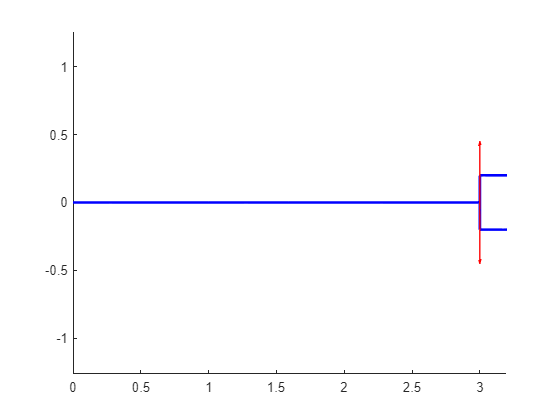

figure
drawPlanarRobot([1,1,1], [q_1, q_2, q_3])
axis equal
v1 = 0.5*[0 1];
v2 = 0.5*[0 -1];
ox = cos(q_1)+cos(q_1+q_2)+cos(q_1+q_2+q_3);
oy = sin(q_1)+sin(q_1+q_2)+sin(q_1+q_2+q_3);
quiver(ox, oy, v1(1), v1(2), 'r');
quiver(ox, oy, v2(1), v2(2), 'r');

#### Caso 2

q_2 = pi;
q_3 = 0;

In questo caso le direzioni consentite sono date da

Jq = subs(J, [q1, q2, q3], [q_1, q_2, q_3])

$$Jq = \left(\begin{array}{ccc} 0 & 0 & 0\\ -1 & -2 & -1 \end{array}\right)$$

null(Jq.')

$$ans = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

colspace(Jq)

$$ans = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

Risulta quindi evidente che le uniche direzioni consentite sono quelle del tipo $\alpha\pmatrix{0 \cr 1}$. Tutti i giunti sono in grado di realizzare tali direzioni in maniera indipendente.

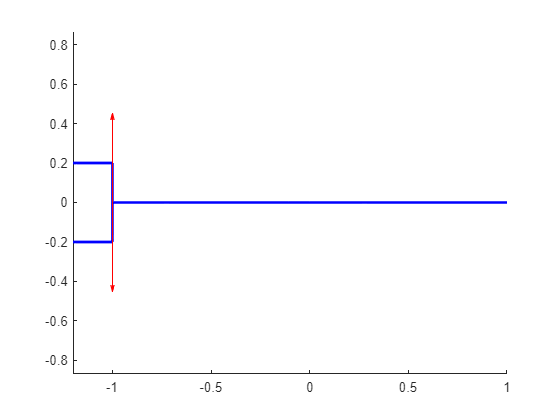

figure
drawPlanarRobot([1,1,1], [q_1, q_2, q_3])
axis equal
v1 = 0.5*[0 1];
v2 = 0.5*[0 -1];
ox = cos(q_1)+cos(q_1+q_2)+cos(q_1+q_2+q_3);
oy = sin(q_1)+sin(q_1+q_2)+sin(q_1+q_2+q_3);
quiver(ox, oy, v1(1), v1(2), 'r');
quiver(ox, oy, v2(1), v2(2), 'r');

#### Caso 3

q_2 = pi;
q_3 = pi;

In questo caso le direzioni consentite sono date da

Jq = subs(J, [q1, q2, q3], [q_1, q_2, q_3])

$$Jq = \left(\begin{array}{ccc} 0 & 0 & 0\\ 1 & 0 & 1 \end{array}\right)$$

null(Jq.')

$$ans = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

colspace(Jq)

$$ans = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

Risulta quindi evidente che le uniche direzioni consentite sono quelle del tipo $\alpha\pmatrix{0 \cr 1}$. Il secondo giunto non contribuisce.

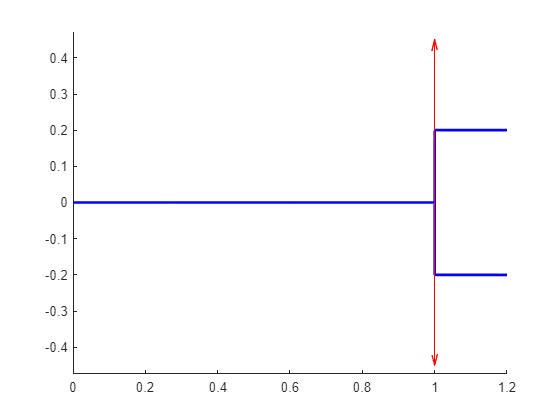

figure
drawPlanarRobot([1,1,1], [q_1, q_2, q_3])
axis equal
v1 = 0.5*[0 1];
v2 = 0.5*[0 -1];
ox = cos(q_1)+cos(q_1+q_2)+cos(q_1+q_2+q_3);
oy = sin(q_1)+sin(q_1+q_2)+sin(q_1+q_2+q_3);
quiver(ox, oy, v1(1), v1(2), 'r');
quiver(ox, oy, v2(1), v2(2), 'r');

#### Caso 4

q_2 = 0;
q_3 = pi;

In questo caso le direzioni consentite sono date da

Jq = subs(J, [q1, q2, q3], [q_1, q_2, q_3])

$$Jq = \left(\begin{array}{ccc} 0 & 0 & 0\\ 1 & 0 & -1 \end{array}\right)$$

null(Jq.')

$$ans = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

colspace(Jq)

$$ans = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

Risulta quindi evidente che le uniche direzioni consentite sono quelle del tipo $\alpha\pmatrix{0 \cr 1}$. Il secondo giunto non contribuisce.

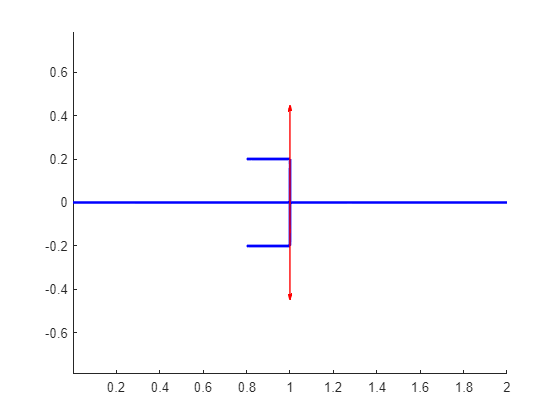

figure
drawPlanarRobot([1,1,1], [q_1, q_2, q_3])
axis equal
v1 = 0.5*[0 1];
v2 = 0.5*[0 -1];
ox = cos(q_1)+cos(q_1+q_2)+cos(q_1+q_2+q_3);
oy = sin(q_1)+sin(q_1+q_2)+sin(q_1+q_2+q_3);
quiver(ox, oy, v1(1), v1(2), 'r');
quiver(ox, oy, v2(1), v2(2), 'r');

#### Caso q_1 diverso da 0

Si vuole ora analizzare un caso in cui $q_1 \neq 0$.

q_1 = pi/6;
q_2 = 0;
q_3 = pi;

In questo caso le direzioni consentite sono date da

Jq = subs(J, [q1, q2, q3], [q_1, q_2, q_3])

$$Jq = \left(\begin{array}{ccc} -\frac{1}{2} & 0 & \frac{1}{2}\\ \frac{\sqrt{3}}{2} & 0 & -\frac{\sqrt{3}}{2} \end{array}\right)$$

null(Jq.')

$$ans = \left(\begin{array}{c} \sqrt{3}\\ 1 \end{array}\right)$$

colspace(Jq)

$$ans = \left(\begin{array}{c} 1\\ -\sqrt{3} \end{array}\right)$$

Risulta quindi evidente che le uniche direzioni consentite sono quelle del tipo $\alpha\pmatrix{-1 \cr \sqrt{3}}$. Il secondo giunto non contribuisce.

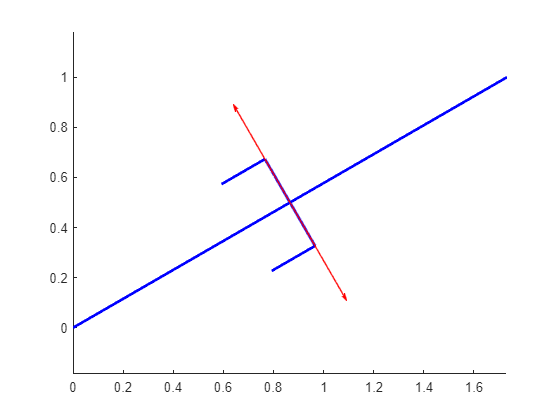

figure
drawPlanarRobot([1,1,1], [q_1, q_2, q_3])
axis equal
v1 = 0.5*[-1 sqrt(3)]/norm([-1 sqrt(3)]);
v2 = 0.5*[1 -sqrt(3)]/norm([1 -sqrt(3)]);
ox = cos(q_1)+cos(q_1+q_2)+cos(q_1+q_2+q_3);
oy = sin(q_1)+sin(q_1+q_2)+sin(q_1+q_2+q_3);
quiver(ox, oy, v1(1), v1(2), 'r');
quiver(ox, oy, v2(1), v2(2), 'r');